clc; clear all; close all;
set(0, 'defaultAxesTickLabelInterpreter','latex'); 
set(0, 'defaultlegendInterpreter','latex')

## **Stacker crane**

#### *Horizontal movement*

%Data:
vh_max= 0.65;% [m/s] velocità massima orizzontale
ah= 0.4;% [m/s^2] accelerazione/decelerazione massima orizzontale

Sh1=15;% O-P1 [m]
Sh2=15;% P1-P2 [m]
Sh3=-30;% P2-O[m]

xv_12h = (vh_max^2)/(ah*abs(Sh1)+(vh_max)^2)

xv_12h = 0.0658

t_12h = (1/(1-xv_12h))*(abs(Sh1)/vh_max)

t_12h = 24.7019

xv_3h = (vh_max^2)/(ah*abs(Sh3)+(vh_max)^2)

xv_3h = 0.0340

t_3h = (1/(1-xv_3h))*(abs(Sh3)/vh_max)

t_3h = 47.7788


mlc_x = CreateLdmComp(6);

mlc_x.disp.um = 'm'; %unit of measure

%first ML
mlc_x.vldm{1}.file = 'ConstSym';
mlc_x.vldm{1}.par.xv = xv_12h;
mlc_x.vldm{1}.name = 'O-P1';
mlc_x.vldm{1}.h = Sh1; %stroke
mlc_x.vldm{1}.ta = t_12h; %drive time [s]

%second ML
mlc_x.vldm{2}.file = 'Stop';
mlc_x.vldm{2}.name = 'unload';
mlc_x.vldm{2}.h = 0; %no movement
mlc_x.vldm{2}.ta = 10; % drive time [s]

%third ML
mlc_x.vldm{3}.file = 'ConstSym';
mlc_x.vldm{3}.par.xv = xv_12h;
mlc_x.vldm{3}.name = 'P1-P2';
mlc_x.vldm{3}.h = Sh2; 
mlc_x.vldm{3}.ta = t_12h; %[s]

%fourth ML
mlc_x.vldm{4}.file = 'Stop';
mlc_x.vldm{4}.name = 'load';
mlc_x.vldm{4}.h = 0; %no movement
mlc_x.vldm{4}.ta = 10; %[s]

%fifth ML
mlc_x.vldm{5}.file = 'ConstSym';
mlc_x.vldm{5}.par.xv = xv_3h;
mlc_x.vldm{5}.name = 'P2-O';
mlc_x.vldm{5}.h = Sh3; 
mlc_x.vldm{5}.ta = t_3h; %[s]

%sixth ML
mlc_x.vldm{6}.file = 'Stop';
mlc_x.vldm{6}.name = 'base station';
mlc_x.vldm{6}.h = 0; %no movement
mlc_x.vldm{6}.ta = 10; %[s]

disp("Legge di moto: movimento orizzontale");

Legge di moto: movimento orizzontale


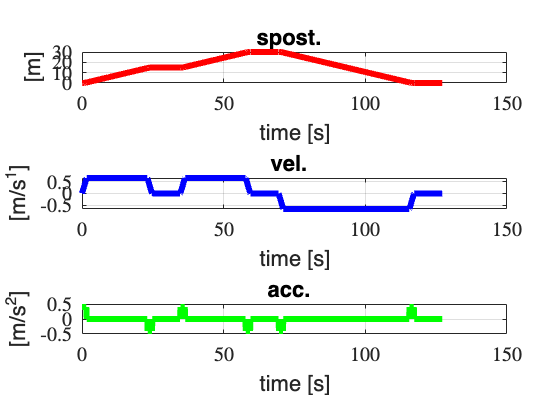

mlc_x = EvalLdmComp(mlc_x,1000);
PlotLdmComp(mlc_x);


% rinomino le variabili in gioco 
x = mlc_x.moto.data{1}.v;
xp = mlc_x.moto.data{2}.v;
xpp = mlc_x.moto.data{3}.v;
tx = mlc_x.moto.time;

#### *Vertical movement*

%Dates:
%vh_max= 1;% [m/s] velocità massima verticale
ah= 0.4;% [m/s^2] accelerazione/decelerazione massima verticale

t_12v = t_12h;
t_3v = t_3h;


Sv1=10;% O-P1 [m]
Sv2=-5;% P1-P2 [m]
Sv3=-5;% P2-O[m]

C1v = abs(Sv1) / (ah * t_12v^2); 
C2v = abs(Sv2) / (ah * t_12v^2); 
C3v = abs(Sv3) / (ah * t_3v^2); 

xv_1v = (1 - sqrt(1 - 4*C1v))/2

xv_1v = 0.0428

xv_2v = (1 - sqrt(1 - 4*C2v))/2

xv_2v = 0.0209

xv_3v = (1 - sqrt(1 - 4*C3v))/2

xv_3v = 0.0055


mlc_y = CreateLdmComp(6);

mlc_y.disp.um = 'm'; %unit of measure

%first ML
mlc_y.vldm{1}.file = 'ConstSym';
mlc_y.vldm{1}.par.xv = xv_1v;
mlc_y.vldm{1}.name = 'O-P1';
mlc_y.vldm{1}.h = Sv1; %stroke
mlc_y.vldm{1}.ta = t_12v; %drive time [s]

%second ML
mlc_y.vldm{2}.file = 'Stop';
mlc_y.vldm{2}.name = 'unload';
mlc_y.vldm{2}.h = 0; %no movement
mlc_y.vldm{2}.ta = 10; % drive time [s]

%third ML
mlc_y.vldm{3}.file = 'ConstSym';
mlc_y.vldm{3}.par.xv = xv_2v;
mlc_y.vldm{3}.name = 'P1-P2';
mlc_y.vldm{3}.h = Sv2; 
mlc_y.vldm{3}.ta = t_12v; %[s] 
% se fosse andato a velocità e accelerazione
% avrebbe impiegato solo 7.5 s non seguendo più lo spostamento orizzontale

%fourth ML
mlc_y.vldm{4}.file = 'Stop';
mlc_y.vldm{4}.name = 'load';
mlc_y.vldm{4}.h = 0; %no movement
mlc_y.vldm{4}.ta = 10; %[s]

%fifth ML
mlc_y.vldm{5}.file = 'ConstSym';
mlc_y.vldm{5}.par.xv = xv_3v;
mlc_y.vldm{5}.name = 'P2-O';
mlc_y.vldm{5}.h = Sv3; 
mlc_y.vldm{5}.ta = t_3v; %[s]
%se fosse andato a velocità e accelerazione
% avrebbe impiegato solo 7.5 s non seguendo più lo spostamento orizzontale

%sixth ML
mlc_y.vldm{6}.file = 'Stop';
mlc_y.vldm{6}.name = 'base station';
mlc_y.vldm{6}.h = 0; %no movement
mlc_y.vldm{6}.ta = 10; %[s]

disp("Legge di moto: movimento verticale");

Legge di moto: movimento verticale


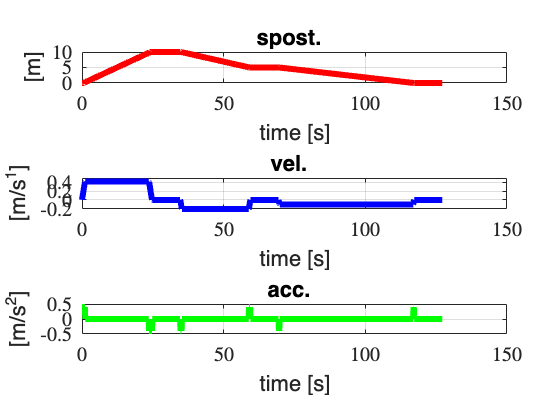

mlc_y = EvalLdmComp(mlc_y,1000);
PlotLdmComp(mlc_y);


% rinomino le variabili in gioco 
y = mlc_y.moto.data{1}.v;
yp = mlc_y.moto.data{2}.v;
ypp = mlc_y.moto.data{3}.v;
ty = mlc_y.moto.time;

# (HORIZONTAL) Adattamento dinamico movimento 

#### DATI CARICO:

Do= 0.32; %[m] diametro della ruota
Ro= Do/2;
fv= 0.009; %coefficiente attrito volvente
Pco= 8000; %[N] peso carrello orizzontale vuoto  
P= 8000; %[N] peso massimo trasportabile
g= 9.81;


#### Calcolo $\omega$  e $\dot{\omega}$ 

wc=xp/Ro; %rad/s
wpc=xpp/Ro; %rad/s^2
wc_max=max(abs(wc)) %rad/s

wc_max = 4.0625

wc_rms=rms(wc)

wc_rms = 3.4287

wpc_max=max(abs(wpc)) %rad/s^2

wpc_max = 2.5000

wpc_rms=rms(wpc) %rad/s^2

wpc_rms = 0.6937

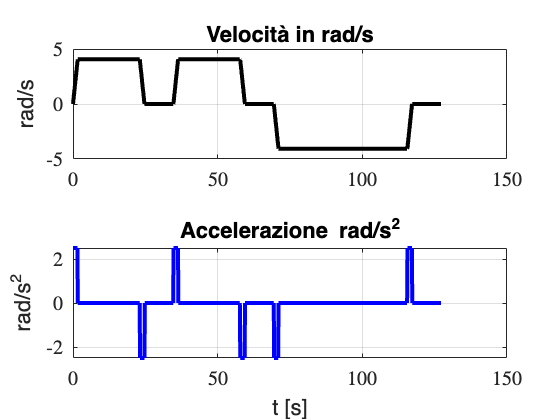


figure('color','white');
subplot(2,1,1);
 plot(ty,wc,'k','linewidth',2);  grid on;
  title('Velocità in rad/s');
ylabel('rad/s')
subplot(2,1,2);
 plot(ty,wpc,'b','linewidth',2);  grid on;
  title('Accelerazione rad/s^2');
  ylabel('rad/s^2')
xlabel('t [s]')

#### Coppia e Potenza carico

for k=1:length(ty)
    if(tx(k)<t_12h)
    
    Ca(k)=(P+Pco)*fv*Ro*sign(wc(k));
    Ci(k)=wpc(k)*(((P+Pco)/g)*Ro^2);

    end
    if (tx(k)>t_12h)&&(tx(k)<2*t_12h+10)
    
    Ca(k)=(Pco)*fv*Ro*sign(wc(k));
    Ci(k)=wpc(k)*(((Pco)/g)*Ro^2);
    end
    if (tx(k)>2*t_12h+10)
    
    Ca(k)=(P+Pco)*fv*Ro*sign(wc(k));
    Ci(k)=wpc(k)*(((P+Pco)/g)*Ro^2);
    
    end
end

Jr = (P+Pco)/g*Ro^2;

Cu=Ca+Ci;
Cu_rms=rms(Cu);

Wc=Cu.*wc;
Wc_rms=rms(Wc);

Lc=mean(Cu.*wpc);

### Grafici coppie e potenza del carico

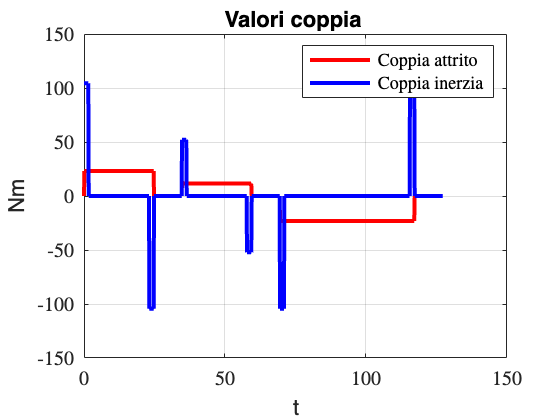

figure('color','white');
plot(tx, Ca,'r',tx,Ci,'b','linewidth',2); grid on;
title('Valori coppia ');
xlabel('t');
ylabel('Nm')
grid on;
legend('Coppia attrito ','Coppia inerzia')

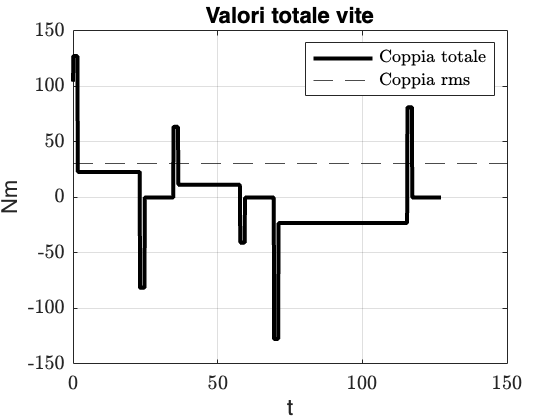


figure('color','white');
plot(tx,Cu,'k','linewidth',2); 
hold on;grid on;
yline(Cu_rms,'k--')
xlabel('t');
ylabel('Nm')
legend('Coppia totale','Coppia rms')
title('Valori totale vite');

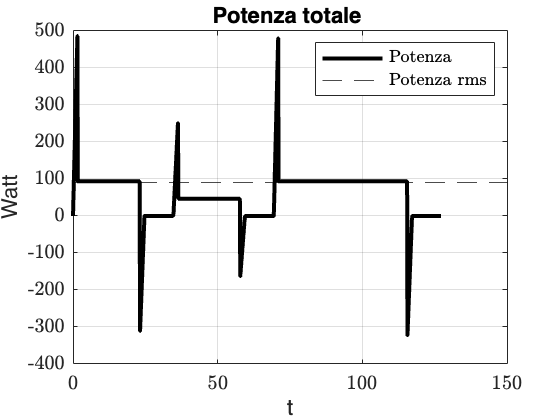


figure('color','white');
plot(tx,Wc,'k','linewidth',2); 
hold on;grid on;
yline(Wc_rms,'k--')
xlabel('t');
ylabel('Watt')
legend('Potenza','Potenza rms')
title('Potenza totale ');


Cu_max=max(abs(Cu))

Cu_max = 127.4233

Wc_max=max(abs(Wc))

Wc_max = 486.6678

Wc_rms=rms(Wc)

Wc_rms = 91.4212

#### Dati per la scelta  inseriti nella  struttura Load

Load.Cu_rms=Cu_rms;    %coppia RMS 
Load.Cu_max=Cu_max;    %coppia massima 
Load.Lc =Lc;           %media del prodotto Cu*wc 
Load.wpc_rms=wpc_rms;    %accelerazione RMS 
Load.wpc_max=wpc_max;    %accelerazione massima
Load.wc_max=wc_max;      %veloctà massima 
disp(Load);

     Cu_rms: 30.7358
     Cu_max: 127.4233
         Lc: 16.5861
    wpc_rms: 0.6937
    wpc_max: 2.5000
     wc_max: 4.0625



### Scelta Motore 

Famiglia di trasmissioni scelta: ESP 100/2

% Velocità massima della trasmissione
nTMax=3000  

nTMax = 3000

m=4;
T.i= 70;
disp("Adattamento dinamico: movimento orizzontale");

Adattamento dinamico: movimento orizzontale


Valore FcOTT = 8.7073
Valore EcOTT = 27.041
Tabella motori e rapporti di trasmissione
         Codice            Jm       CN     Cm_max    nMAX    nMAX1        Pm          Pm_max        Km        Fm      Fm_max      Em       IOTT      Imin      Imax 
    _________________    _______    ___    ______    ____    _____    __________    __________    ______    ______    ______    ______    ______    ______    ______

    {'BMD_{102-7.7}'}    0.00047    7.7    19.25     4500    3000     1.2

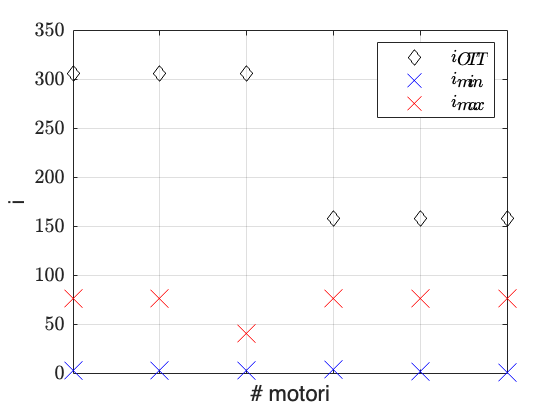

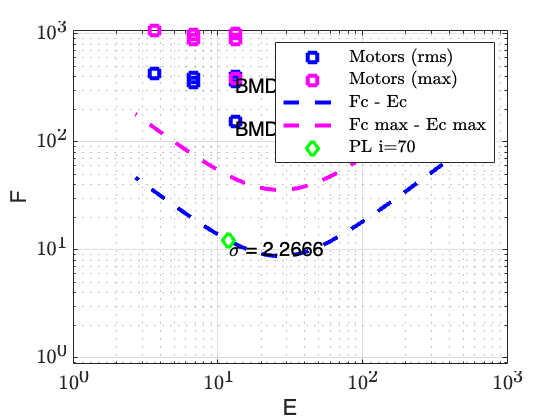

mot = AdattamentoDinamicoZAPPA(@DB_Mot2, Load, nTMax,m,T);

Dai dati si decide:

Cm_max=mot(m).Cm_max;
CN=mot(m).CN;
Jm=mot(m).Jm;
nMAX=min(nTMax,mot(m).nMAX);
wMAX=nMAX*2*pi/60;

disp('Tabella motore scelto');

Tabella motore scelto


Tablemot = struct2table(mot(m));  %solo per visualizzazione
disp(Tablemot);

       Codice          Jm       CN     Cm_max    nMAX    nMAX1     Pm        Pm_max        Km        Fm      Fm_max     Em       IOTT      Imin      Imax 
    _____________    _______    ___    ______    ____    _____    _____    __________    ______    ______    ______    _____    ______    ______    ______

    BMD_{102-6.5}    0.00176    6.5    16.25     6000    3000     24006    1.5004e+05    173.71    154.94    387.34    13.18    158.66    4.7319    77.332



### Verifica

Con il  motore/riduttore scelto  si  calcola la coppia e la potenza erogata dal motore.    

Si  verifica che  $C_{rms}<C_N$ e si calcola il margine di coppia $M_C=\frac{C_N}{C_{rms}}$

Si rappresenta  il ciclo  di carico verificando che sia all'interno del campo intermittente

**Verifica**

%rendimento,inerzia,rapporto T
T.Codice='ESP 100/2';
T.eta=1;%caso ideale
T.i=50;%rapporto di riduzione
T.JT=2.8e-5; %momento inerzia kgm^2 lato motore
T.M2=250; %Nm coppia massima all'uscita

disp('Tabella riduttore scelto');

Tabella riduttore scelto


Tablemot = struct2table(T);  %solo per visualizzazione
disp(Tablemot);

    i      Codice      eta      JT       M2 
    __    _________    ___    _______    ___

    50    ESP 100/2     1     2.8e-05    250




Cm_v=(Cu/(T.eta*T.i))+wpc*T.i*(Jm+T.JT); %coppia motore di verifica
Cm_vrms=rms(Cm_v);
Wm_v=Cm_v.*wc*T.i;
Cm_vmax=max(abs(Cm_v));
MC=CN/Cm_vrms; %determinare margine di coppia

nc=wc*60/(2*pi);
n_mot=T.i*nc;

disp(['Valore di verifica RMS Cm_v = ', num2str(Cm_vrms)] );

Valore di verifica RMS Cm_v = 0.6641


disp(['Valore di verifica MAX Cm_v = ', num2str(Cm_vmax)] );

Valore di verifica MAX Cm_v = 2.772


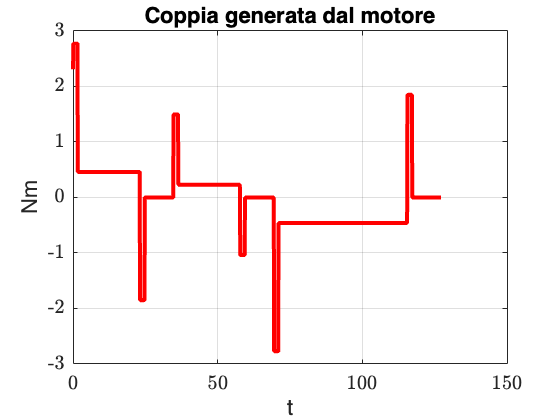


%andamento coppia e potenza
figure('color','white');
plot(tx,Cm_v,'r','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Nm')
title('Coppia generata dal motore');

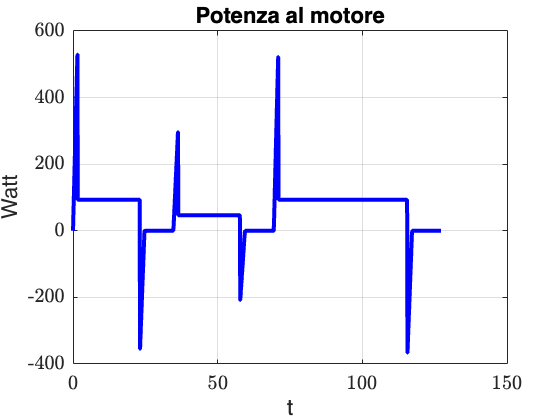


figure('color','white');
plot(tx,Wm_v,'b','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Watt')
title('Potenza al motore');

**Verifica termica**

if(MC>1) disp(['Verifica termina soddisfatta, MC = ', num2str(MC), ' > 1'] );
    else disp(['Verifica termica non soddisfatta,  MC = ', num2str(MC), ' < 1'] );
end

Verifica termina soddisfatta, MC = 9.7876 > 1


**Verifica "picco di coppia" (ciclo di carico)**

Disegno le regioni S1 e Si (approssimazioni a rettangolo)

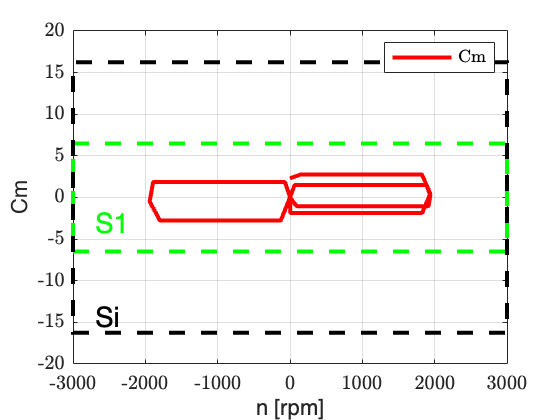

figure
plot(n_mot,Cm_v,'r','linewidth',2 )
rectangle('Position',[-nMAX -CN 2*nMAX 2*CN],'EdgeColor', 'g','LineStyle','--','linewidth',2) 
rectangle('Position',[-nMAX -Cm_max 2*nMAX 2*Cm_max],'EdgeColor','k','LineStyle','--','linewidth',2) 
grid on;
text(-nMAX+nMAX/10,-CN+CN/2,'S1','Color','g','FontSize',14)
text(-nMAX+nMAX/10,-Cm_max+Cm_max/10,'Si','Color','k','FontSize',14)

xlabel('n [rpm]')
ylabel('Cm')
legend('Cm')

# (VERTICAL) Adattamento dinamico movimento 

#### DATI CARICO:

% Working mode
% -0: with counterweigth
% -1: without counterweigth
mode = 0

mode = 0

Dt= 0.2;% diametro tamburo
Dv= 0.182; %[m] diametro delle ruote del carrello (per attrivo volvente)
Rt= Dt/2;% raggio del tamburo che muove la fune
Rv= Dv/2;% raggio delle ruote
fv= 0.009; %coefficiente attrito volvente
Pcv= 3000; %[N] peso carrello vuoto
if mode==0
    Pct= 7000;
else
    Pct= 0;
end
%Pct= 7000;% peso dello contropeso
P= 8000; %[N] peso massimo trasportabile
g= 9.81;

la = 1;
lb = 0.75;
lc = 0.05;
ld = 0.5;


#### Calcolo $\omega$  e $\dot{\omega}$ 

wc=yp/Rt; %rad/s
wpc=ypp/Rt; %rad/s^2
wc_max=max(abs(wc)) %rad/s

wc_max = 4.2293

wc_rms=rms(wc)

wc_rms = 2.1192

wpc_max=max(abs(wpc)) %rad/s^2

wpc_max = 4.0000

wpc_rms=rms(wpc) %rad/s^2

wpc_rms = 0.6928

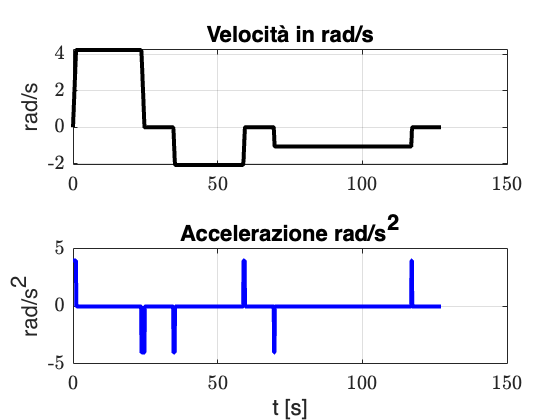


figure('color','white');
subplot(2,1,1);
 plot(ty,wc,'k','linewidth',2);  grid on;
  title('Velocità in rad/s');
ylabel('rad/s')
subplot(2,1,2);
 plot(ty,wpc,'b','linewidth',2);  grid on;
  title('Accelerazione rad/s^2');
  ylabel('rad/s^2')
xlabel('t [s]')

#### Coppia e Potenza carico

for k=1:length(ty)
    if(ty(k)<t_12v || ty(k)>2*t_12v+10)

    N = 1/ld*(Pcv*lc+P*(la/2+lb));
    Fsm=2*N*fv*sign(wc(k));
    Cr(k)=Rt*(P+Pcv+Fsm-Pct); %carico

    N_i=1/ld*(Pcv*lc+P*(la/2+lb))*Rt/g*wpc(k);
    Fsm_i=2*N_i*fv*sign(wc(k))+(P+Pcv)/g*Rt*wpc(k);
    Ci(k)=Rt*(Fsm_i); %inerzia

    end
    if (ty(k)>t_12v)&&(ty(k)<2*t_12v+10)
    
    N = 1/ld*(Pcv*lc);
    Fsm=2*N*fv*sign(wc(k));
    Cr(k)=Rt*(Pcv+Fsm-Pct); %carico

    N_i=1/ld*(Pcv*lc)*Rt/g*wpc(k);
    Fsm_i=2*N_i*fv*sign(wc(k))+Pcv/g*Rt*wpc(k);
    Ci(k)=Rt*(Fsm_i); %inerzia

    end
end

Cu=(Cr+Ci);%coppia totaleg
Cu_rms=rms(Cu);

Wc=Cu.*wc;
Wc_rms=rms(Wc);

Lc=mean(Cu.*wpc);


### Grafici coppie e potenza del carico

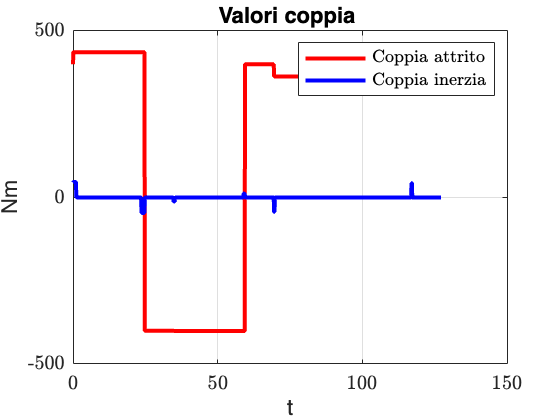

figure('color','white');
plot(ty, Cr,'r',ty,Ci,'b','linewidth',2); grid on;
title('Valori coppia ');
xlabel('t');
ylabel('Nm')
grid on;
legend('Coppia attrito ','Coppia inerzia')

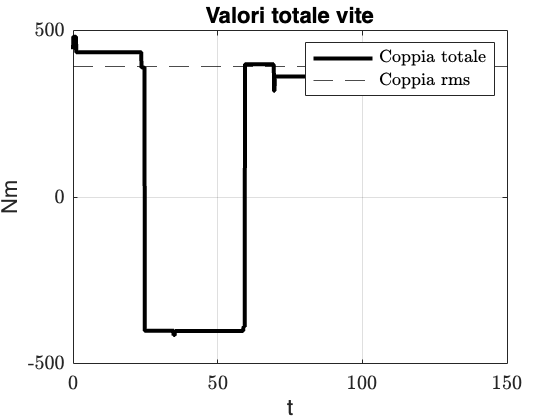


figure('color','white');
plot(ty,Cu,'k','linewidth',2); 
hold on;grid on;
yline(Cu_rms,'k--')
xlabel('t');
ylabel('Nm')
legend('Coppia totale','Coppia rms')
title('Valori totale vite');

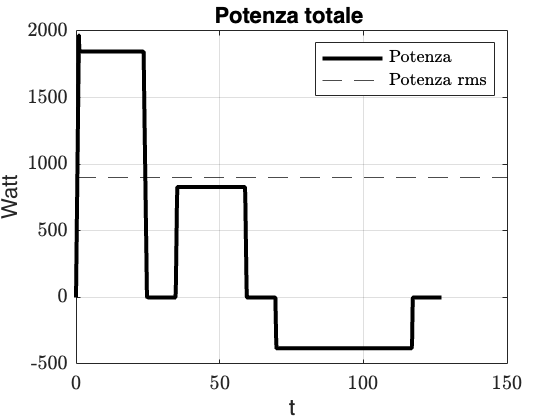


figure('color','white');
plot(ty,Wc,'k','linewidth',2); 
hold on;grid on;
yline(Wc_rms,'k--')
xlabel('t');
ylabel('Watt')
legend('Potenza','Potenza rms')
title('Potenza totale ');


Cu_max=max(abs(Cu))

Cu_max = 482.8821

Wc_max=max(abs(Wc))

Wc_max = 1.9672e+03

Wc_rms=rms(Wc)

Wc_rms = 898.6607

#### Dati per la scelta  inseriti nella  struttura Load

Load.Cu_rms=Cu_rms;    %coppia RMS 
Load.Cu_max=Cu_max;    %coppia massima 
Load.Lc =Lc;           %media del prodotto Cu*wc 
Load.wpc_rms=wpc_rms;    %accelerazione RMS 
Load.wpc_max=wpc_max;    %accelerazione massima
Load.wc_max=wc_max;      %veloctà massima 
disp(Load);

     Cu_rms: 394.4556
     Cu_max: 482.8821
         Lc: 4.2690
    wpc_rms: 0.6928
    wpc_max: 4.0000
     wc_max: 4.2293



### Scelta Motore 

Famiglia di trasmissioni scelta: ESP 180/2

% Velocità massima della trasmissione
nTMax=3000    

nTMax = 3000

m=11;
T.i= 70;
disp("Adattamento dinamico: movimento orizzontale");

Adattamento dinamico: movimento orizzontale


Valore FcOTT = 23.5608
Valore EcOTT = 100.9153
Tabella motori e rapporti di trasmissione
          Codice            Jm        CN     Cm_max    nMAX    nMAX1        Pm          Pm_max        Km        Fm      Fm_max      Em       IOTT      Imin      Imax 
    __________________    _______    ____    ______    ____    _____    __________    __________    ______    ______    ______    ______    ______    ______    ______

    {'BMD_{102-7.7}' }    0.00047     7.7    19.25     4500    300

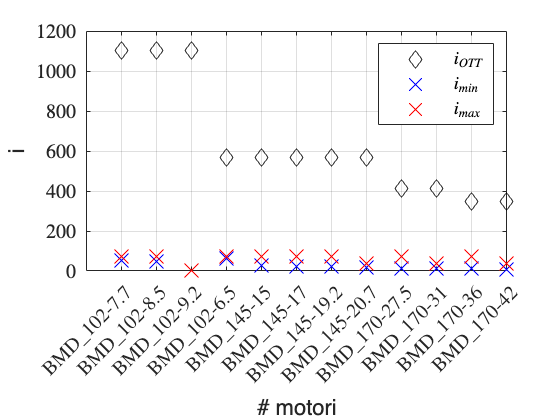

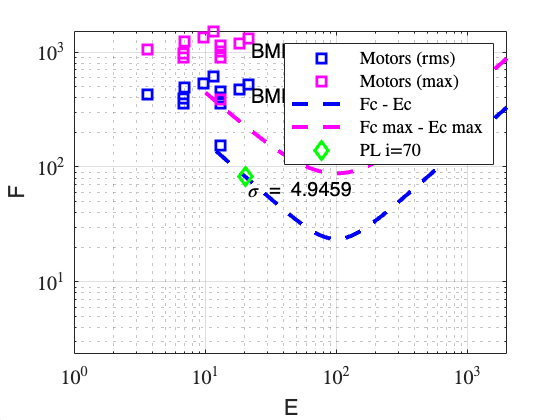

mot = AdattamentoDinamicoZAPPA(@DB_Mot3, Load, nTMax, m, T);

Dai dati si decide:

Cm_max=mot(m).Cm_max;
CN=mot(m).CN;
Jm=mot(m).Jm;
nMAX=min(nTMax,mot(m).nMAX);
wMAX=nMAX*2*pi/60;

disp('Tabella motore scelto');

Tabella motore scelto


Tablemot = struct2table(mot(m));  %solo per visualizzazione
disp(Tablemot);

       Codice         Jm       CN    Cm_max    nMAX    nMAX1        Pm          Pm_max        Km        Fm      Fm_max      Em       IOTT      Imin      Imax 
    ____________    _______    __    ______    ____    _____    __________    __________    ______    ______    ______    ______    ______    ______    ______

    BMD_{170-36}    0.00475    36      90      3000    3000     2.7284e+05    1.7053e+06    468.81    522.34    1305.9    21.652    346.21    10.957    74.282



### Verifica

Con il  motore/riduttore scelto  si  calcola la coppia e la potenza erogata dal motore.    

Si  verifica che  $C_{rms}<C_N$ e si calcola il margine di coppia $M_C=\frac{C_N}{C_{rms}}$

Si rappresenta  il ciclo  di carico verificando che sia all'interno del campo intermittente

**Verifica**

%rendimento,inerzia,rapporto T
T.Codice='ESP 180/2';
T.eta=1;%caso ideale
% T.i=70;%rapporto di riduzione
T.JT=1.2e-4; %momento inerzia kgm^2 lato motore
T.M2=900; %Nm coppia massima all'uscita

disp('Tabella riduttore scelto');

Tabella riduttore scelto


Tablemot = struct2table(T);  %solo per visualizzazione
disp(Tablemot);

    i      Codice      eta      JT       M2 
    __    _________    ___    _______    ___

    70    ESP 180/2     1     0.00012    900




Cm_v=(Cu/(T.eta*T.i))+wpc*T.i*(Jm+T.JT); %coppia motore di verifica
Cm_vrms=rms(Cm_v);
Wm_v=Cm_v.*wc*T.i;
Cm_vmax=max(abs(Cm_v));
MC=CN/Cm_vrms; %determinare margine di coppia

nc=wc*60/(2*pi);
n_mot=T.i*nc;

disp(['Valore di verifica RMS Cm_v = ', num2str(Cm_vrms)] );

Valore di verifica RMS Cm_v = 5.6437


disp(['Valore di verifica MAX Cm_v = ', num2str(Cm_vmax)] );

Valore di verifica MAX Cm_v = 8.2619


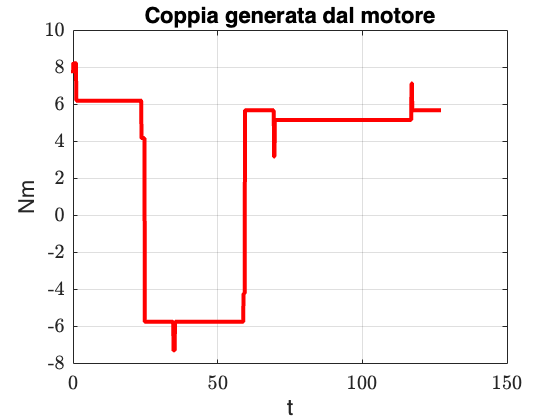


%andamento coppia e potenza
figure('color','white');
plot(tx,Cm_v,'r','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Nm')
title('Coppia generata dal motore');

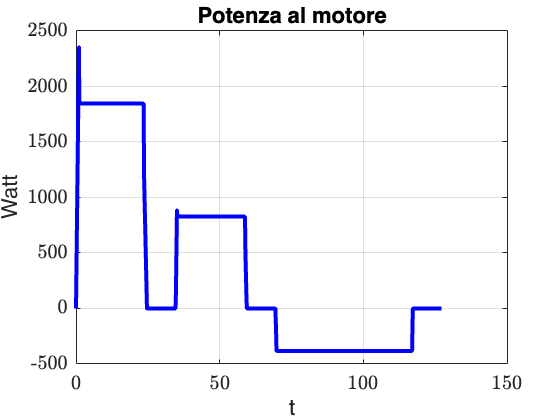


figure('color','white');
plot(tx,Wm_v,'b','linewidth',2); 
hold on;grid on;
xlabel('t');
ylabel('Watt')
title('Potenza al motore');

**Verifica termica**

if(MC>1) disp(['Verifica termina soddisfatta, MC = ', num2str(MC), ' > 1'] );
    else disp(['Verifica termica non soddisfatta,  MC = ', num2str(MC), ' < 1'] );
end

Verifica termina soddisfatta, MC = 6.3788 > 1


**Verifica "picco di coppia" (ciclo di carico)**

Disegno le regioni S1 e Si (approssimazioni a rettangolo)

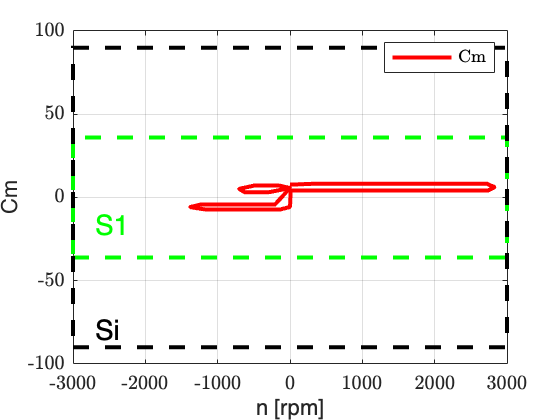

figure
plot(n_mot,Cm_v,'r','linewidth',2 )
rectangle('Position',[-nMAX -CN 2*nMAX 2*CN],'EdgeColor', 'g','LineStyle','--','linewidth',2) 
rectangle('Position',[-nMAX -Cm_max 2*nMAX 2*Cm_max],'EdgeColor','k','LineStyle','--','linewidth',2) 
grid on;
text(-nMAX+nMAX/10,-CN+CN/2,'S1','Color','g','FontSize',14)
text(-nMAX+nMAX/10,-Cm_max+Cm_max/10,'Si','Color','k','FontSize',14)

xlabel('n [rpm]')
ylabel('Cm')
legend('Cm')